clc; clear;
g = 9.81;
y0 = 25;
v0 = 30;
dt = 0.11

dt = 0.1100

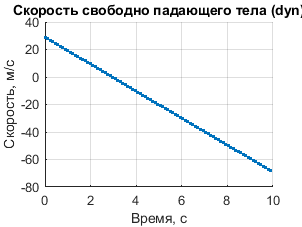

t = 0:dt:10;

y = y0 + v0 * t - g * t.^2 / 2; 

v_d = v0 - cumsum(repmat(g, size(t)) * dt);
y_d = y0 + cumsum(v_d * dt);

scatter(t, v_d, '.')
xlabel('Время, с')
ylabel('Скорость, м/с')
grid on
title('Скорость свободно падающего тела (dyn)')
saveas(gcf, 'speed_dyn.png')

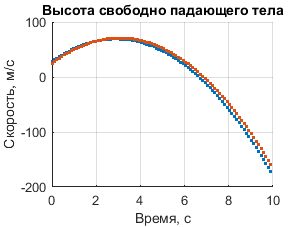


scatter(t, y_d, '.', 'DisplayName', 'Динамическая модель')
hold on
scatter(t, y, '.', 'DisplayName', 'Кинетическая модель')
xlabel('Время, с')
ylabel('Скорость, м/с')
grid on
title('Высота свободно падающего тела')
hold off
saveas(gcf, 'dyn+kin.png')